# ความน่าจะเป็นและสัญญาณสุ่ม (Probability & Random Signal)

# ตอนที่ 1 : ความไม่แน่นอนในกรณีที่แย่ที่สุด (Worst case Uncertainty)

ความไม่แน่นอน (uncertainty) เห็นพบได้ในระบบทางกายภาพทั่วไป บางระบบนั้นอาจจะได้รับผลกระทบจากความไม่แน่นอนมากกว่าระบบอื่น นั่นหมายความว่าผลตอบสนองของระบบนั้นสามารถเป็นได้หลากหลาย เราจึงจำเป็นต้องระบุความไม่แน่นอนในระบบเท่าที่ทำได้ และ ออกแบบตัวกรอง ระบบประมาณค่า หรือ ระบบควบคุม ที่จัดการความไม่แน่นอนนั้น

**หนึ่งค่าที่บ่งบอกถึงลักษณะสำคัญของระบบคือพารามิเตอร์ (parameter) ซึ่งเป็นค่าคงที่ในระบบ ปัญหาในการวิเคราะห์หรือการออกแบบคือการที่เราไม่ทราบค่าที่แน่ชัดของค่าคงที่เหล่านี้** ดังนั้นเราสามารถเขียนค่าคงที่และบอกขอบเขตความไม่แน่นอนของค่าเหล่าได้ดังนี้


$$e=\hat{e} \pm \delta e$$


โดยที่ 

$e$ คือค่าของพารามิเตอร์ 

$\hat{e}$ คือค่าประมาณที่ดีที่สุด (best estimate)

$\delta e$ คือค่าความไม่แน่นอนสัมบูรณ์ที่มีค่ามากที่สุดซึ่งมีหน่วยเดียวกันกับค่า $\hat{e}$ ซึ่งจะเป็นค่าบวกเสมอ

ความไม่แน่นอนที่ดเขียนในรูปบวกลบนั้นระบุถึงกรณีที่แย่ที่สุดที่ (worst case) จะเกิดขึ้นได้จริง ดังนั้นค่าที่มีความไม่แน่นอนนี้จะอยู่ในช่วง $\left\lbrack \hat{e} -\delta \;e,\hat{e} +\delta \;e\right\rbrack$  

**การอธิบายความไม่แน่นอนในลักษณะดังกล่าวมีข้อดีในเรื่องของการออกแบบและวิเคราะห์ให้ครอบคลุม เราสามารถออกแบบระบบที่คงทน (robust) และทำงานอยู่ในช่วงได้ **

## การบวกลบกันของความไม่แน่นอน

กำหนดให้ชิ้นงาน  2 ชิ้นวางต่อกันโดยที่ชิ้นงานแรกมีความยาวเท่ากับ ${\hat{e} }_1 \pm \delta e_1$ ชิ้นงานอีกชิ้นหนึ่งมีความยาวเท่ากับ ${\hat{e} }_2 \pm \delta e_2$ ดังนั้นหากเราเอาชิ้นงานวางต่อกัน ความยาวสูงสุดของชิ้นงานที่เป็นไปได้ $e_{\max }$ สามารถเขียนได้ดังต่อไปนี้


$$e_{\max } =\left({\hat{e} }_1 +\delta e_1 \right)+\left({\hat{e} }_2 +\delta e_2 \right)$$


ความยาวต่ำสุดของชิ้นงานที่เป็นไปได้ $e_{\min }$ เป็นดังต่อไปนี้


$$e_{\min } =\left({\hat{e} }_1 -\delta e_1 \right)+\left({\hat{e} }_2 -\delta e_2 \right)$$


หากเราเขียนอยู่ในรูป $\pm$ เราจะสามารถเขียนได้ดังต่อไปนี้


$$\begin{array}{l}
e=\left({\hat{e} }_1 +{\hat{e} }_2 \right)\pm \frac{e_{\max } -e_{\min } }{2}\\
e=\left({\hat{e} }_1 +{\hat{e} }_2 \right)\pm \frac{\left({\hat{e} }_1 +\delta e_1 \right)+\left({\hat{e} }_2 +\delta e_2 \right)-\left({\hat{e} }_1 -\delta e_1 \right)-\left({\hat{e} }_2 -\delta e_2 \right)}{2}\\
e=\left({\hat{e} }_1 +{\hat{e} }_2 \right)\pm \frac{2\left(\delta e_1 +\delta e_2 \right)}{2}\\
e=\left({\hat{e} }_1 +{\hat{e} }_2 \right)\pm \left(\delta e_1 +\delta e_2 \right)
\end{array}$$


เมื่อนำค่ามาบวกรวมกัน ความไม่แน่นอนของแต่ละค่าก็จะเอามารวมกันด้วยเช่นกัน

ในกรณีที่เรามีชิ้นงานที่มีความยาว ${\hat{e} }_1 \pm \delta e_1$ เราทำการใช้เครื่องมือตัดชิ้นส่วนโดยวัดจากขอบไปเป็นความยาว ${\hat{e} }_2 \pm \delta e_2$ เราจะหาความยาวของชิ้นงานที่โดนตัดได้ดังต่อไปนี้


$$\begin{array}{l}
e_{\max } =\left({\hat{e} }_1 +\delta e_1 \right)-\left({\hat{e} }_2 -\delta e_2 \right)\\
e_{\min } =\left({\hat{e} }_1 -\delta e_1 \right)-\left({\hat{e} }_2 +\delta e_2 \right)
\end{array}$$


หากเราเขียนอยู่ในรูป $\pm$ เราจะสามารถเขียนได้ดังต่อไปนี้


$$\begin{array}{l}
e=\left({\hat{e} }_1 -{\hat{e} }_2 \right)\pm \frac{p_{\max } -p_{\min } }{2}\\
e=\left({\hat{e} }_1 -{\hat{e} }_2 \right)\pm \frac{\left({\hat{e} }_1 +\delta e_1 \right)-\left({\hat{e} }_2 -\delta e_2 \right)-\left({\hat{e} }_1 -\delta e_1 \right)+\left({\hat{e} }_2 +\delta e_2 \right)}{2}\\
e=\left({\hat{e} }_1 -{\hat{e} }_2 \right)\pm \frac{2\left(\delta e_1 +\delta e_2 \right)}{2}\\
e=\left({\hat{e} }_1 -{\hat{e} }_2 \right)\pm \left(\delta e_1 +\delta e_2 \right)
\end{array}$$


ถึงแม้ว่าเราจะนำค่าสองค่ามาลบกัน แต่ความไม่แน่นอนจะถูกรวมกัน

## การคูณและหารกันของความไม่แน่นอน

แทนที่เราจะวิเคราะห์ความไม่แน่นอนในเชิงสัมบูรณ์ เราสามารถวิเคราะห์ความไม่แน่นอนแบบสัมพัทธ์ $\delta^r e$ ได้ (relative uncertainty) ซึ่งสามารถคำนวณได้ตามความสัมพันธ์ดังต่อไปนี้


$$\delta^r e=\frac{\delta e}{\left|\hat{e} \right|}$$


โดยที่ $\delta^ˆ e$ คือความไม่แน่นอนสัมพัทธ์ของค่า $e$

สมมุติว่าแผนชิ้นงานถูกกำหนดมาให้มีรูปร่างเป็นสี่เหลี่ยมผืนผ้าที่มีความยาวเท่ากับ ${\hat{e} }_1 \pm \delta e_1$ และมีความยาวเท่ากับ ${\hat{e} }_2 \pm \delta e_2$ หากเราต้องการหาพื้นที่หรือผลคูณระหว่างความยาวและความกว้าง เราสามารถหาความไม่แน่นอนจากการรวมกันของความไม่แน่นอนสัมพัทธ์ซึ่งเขียนเป็นสมการได้ดังต่อไปนี้


$$\frac{\delta e}{\left|\hat{e} \right|}=\frac{\delta e_1 }{\left|{\hat{e} }_1 \right|}+\frac{\delta e_2 }{\left|{\hat{e} }_2 \right|}$$



$$\begin{array}{l}
\hat{e} \pm \delta e=\left({\hat{e} }_1 \cdot {\hat{e} }_2 \right)\pm \left|{\hat{e} }_1 \cdot {\hat{e} }_2 \right|\cdot \frac{\delta e_1 }{\left|{\hat{e} }_1 \right|}+\left|{\hat{e} }_1 \cdot {\hat{e} }_2 \right|\frac{\delta e_2 }{\left|{\hat{e} }_2 \right|}\\
\hat{e} \pm \delta e=\left({\hat{e} }_1 \cdot {\hat{e} }_2 \right)\pm \left|\frac{{\hat{e} }_1 \cdot {\hat{e} }_2 }{{\hat{e} }_1 }\right|\cdot \delta e_1 +\left|\frac{{\hat{e} }_1 \cdot {\hat{e} }_2 }{{\hat{e} }_2 }\right|\cdot \delta e_2 \\
\hat{e} \pm \delta e=\left({\hat{e} }_1 \cdot {\hat{e} }_2 \right)\pm \left|{\hat{e} }_2 \right|\cdot \delta e_1 +\left|{\hat{e} }_1 \right|\cdot \delta e_2 
\end{array}$$


สมมุติว่าเราต้องการคำนวณความชันของเส้นโดยกำหนดความต่างในแนวตั้งเป็น $e_1 \pm \delta e_1$ และ ความต่างในแนวนอนเป็น $e_2 \pm \delta e_2$ เราสามารถหาผลหารได้ในลักษณะเดียวกันกับผลคูณซึ่งเขียนเป็นสมการได้ดังต่อไปนี้


$$\frac{\delta e}{\left|\hat{e} \right|}=\frac{\delta e_1 }{\left|{\hat{e} }_1 \right|}+\frac{\delta e_2 }{\left|{\hat{e} }_2 \right|}$$



$$\begin{array}{l}
\hat{e} \pm \delta e=\left(\frac{{\hat{e} }_1 }{{\hat{e} }_2 }\right)\pm \left|\frac{{\hat{e} }_1 }{{\hat{e} }_2 }\right|\cdot \frac{\delta e_1 }{\left|{\hat{e} }_1 \right|}+\left|\frac{{\hat{e} }_1 }{{\hat{e} }_2 }\right|\cdot \frac{\delta e_2 }{\left|{\hat{e} }_2 \right|}\\
\hat{e} \pm \delta e=\left(\frac{{\hat{e} }_1 }{{\hat{e} }_2 }\right)\pm \left|\frac{{\hat{e} }_1 }{{\hat{e} }_1 \cdot {\hat{e} }_2 }\right|\cdot \delta e_1 +\left|\frac{{\hat{e} }_1 }{{\hat{e} }_2^2 }\right|\cdot \delta e_2 \\
\hat{e} \pm \delta e=\left(\frac{{\hat{e} }_1 }{{\hat{e} }_2 }\right)\pm \frac{1}{{\hat{e} }_2^2 }\cdot \left(\left|{\hat{e} }_2 \right|\cdot \delta e_1 +\left|{\hat{e} }_1 \right|\cdot \delta e_2 \right)
\end{array}$$


## ผลรวมเชิงเส้น (Linear Combination)

กำหนดให้ค่าที่ต้องคำนวณสามารถเขียนในรูปขงผลรวมเชิงเส้น (linear combination) ได้ดังต่อไปนี้


$$\begin{array}{l}
e=a_1 \cdot \left({\hat{e} }_1 \pm \delta e_1 \right)+a_2 \cdot \left({\hat{e} }_2 \pm \delta e_2 \right)+\cdots \\
e=\sum_{k=1}^n \left\lbrace a_k \cdot \left({\hat{e} }_k \pm \delta e_k \right)\right\rbrace 
\end{array}$$


โดยที่ $a_k$ อาจจะเป็นบวกหรือลบก็ได้

เราสามารถหาค่าความคลาดเคลื่อนได้ดังต่อไปนี้


$$e=\sum_{k=1}^n \left\lbrace a_k \cdot {\hat{e} }_k \right\rbrace \pm \sum_{k=1}^n \left\lbrace \left|a_k \right|\cdot \delta e_k \right\rbrace$$


## การยกกำลังของความไม่แน่นอน

หากเรามีค่าที่มีความไม่แน่นอนที่โดนยกกำลัง เราสามารถหาความไม่แน่นอนได้โดยทำการคูณความไม่แน่นอนสัมพัทธ์เดิมด้วยเลขยกกำลัง 


$$\begin{array}{l}
p={\left(\hat{e} \pm \delta e\right)}^n \\
\frac{\delta p}{\left|\hat{p} \right|}=\left|n\right|\frac{\delta e}{\left|\hat{e} \right|}\\
\delta p=\left|n{\hat{e} }^{n-1} \right|\delta e
\end{array}$$


## การประมาณความไม่แน่นอนด้วยอนุพันธ์

ในกรณีที่ความสัมพันธ์เป็นฟังก์ชันไม่เชิงเส้น เราสามารถประมาณความไม่แน่นอนจากนิยามของอนุพันธ์ กำหนดให้ความสัมพันธ์เป็นดังต่อไปนี้


$$p=f\left(e\right)$$


เราะสามารถประมาณความไม่แน่นอนได้โดยใช้นิยามดังต่อไปนี้


$$\frac{\delta p}{\delta e}\approx {\left|\frac{\mathrm{d}}{\mathrm{d}\;e}\left(f\left(e\right)\right)\right|}_{e=\hat{e} }$$


ดังนั้นเราจะได้ความสัมพันธ์ดังต่อไปนี้


$$p\approx \hat{e} \pm {\left|\frac{\mathrm{d}}{\mathrm{d}\;e}\left(f\left(e\right)\right)\right|}_{e=\hat{e} } \cdot \delta e$$


เข้น


$$\begin{array}{l}
\cos \left(p\right)=\cos \left(\hat{e} \pm \delta e\right)\\
\cos \left(p\right)=\cos \left(\hat{e} \right)\pm \delta p=\cos \left(\hat{e} \right)\pm {\left|\frac{\mathrm{d}}{\mathrm{d}\;e}\cos \left(e\right)\right|}_{e=\hat{e} } \cdot \delta e\\
\cos \left(p\right)=\cos \left(\hat{e} \right)\pm \left|-\sin \left(\hat{e} \right)\right|\cdot \delta e
\end{array}$$


## การประยุกต์ใช้ความไม่แน่นอนของระบบ

เมื่อกล่าวถึงการจำลอง (simulation) คนส่วนมากมักจะคิดถึงการจำลองในอุดมคติที่มีค่าพารามิเตอร์ที่ชัดเจน แต่**ในโลกความเป็นจริง เราอาจจะไม่สามารถทราบค่าที่ชัดเจนของพารามิเตอร์เหล่านี้ เพื่อที่จะจำลองให้มีลักษณะที่ครอบคลุมหรือใกล้เคียงกับการทดลองจริง เ**รา**สามารถประยุกต์ใช้ความไม่แน่นอนนี้ได้** หากเราสามารถกำหนดช่วงของพารามิเตอร์เหล่านี้ได้ เราจะสามารถจำลองเป็นจำนวนหลายครั้งได้โดยเปลี่ยนแปลงพารามิเตอร์ในช่วงความไม่แน่นอนที่คำนวณมา

## ตัวอย่างที่ 1 : การจำลองพลวัต

ตัวอย่างนี้เป็นการทดลองเพื่อวัดหาเวลาที่ทำให้วัตถุหยุดจากความเร็วเชิงมุมที่คงที่ $\omega^*$

วัตถุที่ถูกทำให้หมุนเป็นวัตถุทรงปริซึมสี่เหลี่ยมผืนผ้าซึ่งสามารถหาความเฉื่อยในแนวแกนหมุนตามสมการดังต่อไปนี้


$$J=\frac{1}{12}m\left(a^2 +b^2 \right)+{\textrm{ml}}^2$$


โดยที่ 

$a$ และ $b$ เป็นความกว้างและความยาวของวัตถุ $\left\lbrack m\right\rbrack$

$l$ เป็นระยะห่างระหว่างจุดศูนย์กลางมวลและแกนในการหมุน  $\left\lbrack m\right\rbrack$

$m$ เป็นมวลของวัตถุ $\left\lbrack \textrm{kg}\right\rbrack$

นอกจากนี้ ระบบที่โดนหมุนได้เชื่อมต่อกับตลับลูกปืนที่มีความฝืดเชิงมุมเท่ากับ $B$ $\left\lbrack \frac{\mathrm{N}\cdot \mathrm{m}\cdot \mathrm{s}}{\textrm{rad}}\right\rbrack$

และมีพลวัตตามสมการดังต่อไปนี้


$$\begin{array}{l}
J\cdot \frac{\mathrm{d}}{\mathrm{d}\;t}\left(\omega \right)=-B\cdot \omega \\
\omega \left(0\right)=\omega^* 
\end{array}$$


เราจะนิยามระยะเวลาในการหยุดของวัตถุ $T_s$ ให้เป็นระยะเวลาที่ความเร็วของวัตถุมีความเร็วเหลือแค่ 2% ของความเร็วเริ่มต้น


$$\omega \left(T_s \right)=0\ldotp 02\cdot \omega^*$$


นอกจากลักษณะและความสัมพันธ์ของระบบและพารามิเตอร์ที่บอกมา ค่าต่างๆและความไม่แน่นอนถูกกำหนดมาดังนี้


$$\left\lbrack \begin{array}{ccccc}
\textrm{พารามิเตอร์} &  & \textrm{ค่าของพารามิเตอร์} &  & \textrm{หน่วย}\\
\omega^*  &  & 60\pm 2\ldotp 5\; &  & \textrm{rpm}\\
B &  & 0\ldotp 067\pm 0\ldotp 034\; &  & \frac{\mathrm{N}\cdot \mathrm{m}\cdot \mathrm{s}}{\textrm{rad}}\\
m &  & 1\ldotp 343\pm 0\ldotp 001 &  & \textrm{kg}\\
a &  & 0\ldotp 35\pm 0\ldotp 005 &  & \mathrm{m}\\
b &  & 0\ldotp 25\pm 0\ldotp 005 &  & \mathrm{m}\\
l &  & 0\ldotp 05\pm 0\ldotp 005 &  & \mathrm{m}
\end{array}\right\rbrack$$


หนึ่งในวิธีที่เราสามารถจำลองระบบให้ครอบคลุมได้คือการกำหนดให้พารามเตอร์มีค่าที่เป็นได้

**หากเรากำหนดค่าพารามิเตอร์ในรูปแบบดังกล่าว เราจะต้องจำลองทั้งหมด **${11}^6$** หรือมากกว่า 1.7 ล้านครั้ง** แต่ถ้าหากเราหาความไม่แน่นอนและรวมพารามิเตอร์บางตัวได้ เราจะสามารถลดการคำนวณได้อีก เราทำการย้ายพารามิเตอร์ของระบบให้เป็นดังต่อไปนี้


$$\begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}\;t}\left(\omega \right)=-\frac{1}{\tau }\cdot \omega \\
\tau =\frac{J}{B}
\end{array}$$


เราคำนวณค่าความไม่แน่นอนของพารามิเตอร์ $k$ได้ดังต่อไปนี้


$$\begin{array}{l}
\delta \tau =\tau^ˆ \cdot \left(\frac{\delta J}{\hat{J} }+\frac{\delta B}{\hat{B} }\right)\\
\delta J=\frac{1}{12}\delta \left\lbrace m\left(a^2 +b^2 \right)\right\rbrace +\delta \left\lbrace {\textrm{ml}}^2 \right\rbrace \\
\delta J=\frac{1}{12}\cdot \left\lbrack \hat{m} \cdot \delta \left\lbrace \left(a^2 +b^2 \right)\right\rbrace +\left({\hat{a} }^2 +{\hat{b} }^2 \right)\cdot \delta m\right\rbrack +\left\lbrack \hat{m} \cdot \delta \left\lbrace l^2 \right\rbrace +{\hat{l} }^2 \cdot \delta m\right\rbrack \\
\delta J=\frac{1}{12}\cdot \left\lbrack \hat{m} \cdot \left(2\hat{a} \cdot \delta a+2\hat{b} \cdot \delta b\right)+\left({\hat{a} }^2 +{\hat{b} }^2 \right)\cdot \delta m\right\rbrack +\left\lbrack \hat{m} \cdot 2\hat{l} \cdot \delta l+{\hat{l} }^2 \cdot \delta m\right\rbrack \\
\delta J=\left(\frac{\hat{m} \hat{a} }{6}\right)\cdot \delta a+\left(\frac{\hat{m} \hat{b} }{6}\right)\cdot \delta b+\left(\frac{{\hat{a} }^2 +{\hat{b} }^2 }{12}+{\hat{l} }^2 \right)\cdot \delta m+\left(2\hat{m} \hat{l} \right)\cdot \delta l
\end{array}$$


ผลที่ได้คือค่า $k$ ที่มีค่าเท่ากับ $2\ldotp 7845\pm 1\ldotp 5705\;\left\lbrack {\mathrm{s}}^{-1} \right\rbrack$


$$\left\lbrack \begin{array}{ccccc}
\textrm{พารามิเตอร์} &  & \textrm{ค่าของพารามิเตอร์} &  & \textrm{หน่วย}\\
\omega^*  &  & 60\pm 2\ldotp 5\; &  & \textrm{rpm}\\
k &  & 0\ldotp 3591\pm 0\ldotp 2026 &  & \mathrm{s}
\end{array}\right\rbrack$$


เราจะสังเกตได้ว่า **พารามิเตอร์ที่ไม่แน่นอนนั้นถูกลดจำนวนจาก 6 ตัวเหลือแค่ 2 ตัว ทำให้ตำนวนครั้งในการจำลองลดลงเหลือ **$121$** ครั้ง** หากการจำลองหนึ่งครั้งต้องใช้เวลา $0\ldotp 1\;\left\lbrack \mathrm{s}\right\rbrack$ เ**ดิมทีเราต้องใช้เวลา 49 ชั่วโมงในการจำลอง แต่การลดจำนวนตัวแปรทำให้การจำลองลดเวลาเหลือแค่ 12 วินาที**

N = 11;
w_e = 60;
w_0 = 60+2.5*linspace(-1,1,N);
tau_e = 0.3591;
tau = 0.3591+0.2026*linspace(-1,1,N);
% at2percent = @(t,y,w_e)deal(y==0.002*w_e,1,-1);
opt = odeset('Events',@(t,y)at2percent(t,y,w_e));
t_max = 10*tau_e;
tspan = [0 t_max];
T_s = zeros(N,N);
for i = 1:N
    for j = 1:N
        [t,y] = ode45(@(t,y)-y/tau(j),tspan,w_0(i),opt);
        T_s(i,j) = t(end);
    end
end

[T,W] = meshgrid(tau,w_0);
clf
ax = axes;
surf(ax,T,W,T_s)
xlabel('$tau$','Interpreter',"latex")
ylabel('$w_0$','Interpreter',"latex")
zlabel('$T_s$','Interpreter',"latex")
T_mean = mean(T_s,'all');
T_max = max(T_s,[],'all');
T_min = min(T_s,[],'all');

จากจำลอง 121 ครั้ง ค่าเฉลี่ยที่ $2\ldotp 2319\;\left\lbrack \mathrm{s}\right\rbrack$ ค่าที่มากที่สุดที่ $3\ldotp 5139\;\left\lbrack \mathrm{s}\right\rbrack$ และค่าที่น้อยที่สุดที่ $0\ldotp 9661\;\left\lbrack \mathrm{s}\right\rbrack$ ซึ่งเราเขียนเป็นความไม่แน่นอนได้ที่ $2\ldotp 2319\pm 1\ldotp 2820\;\left\lbrack \mathrm{s}\right\rbrack$ สาเหตุที่ความไม่แน่นอนสัมพันธ์อยู๋ที่ $57\ldotp 44\;%$ ก็เพราะว่าความไม่แน่นอนของค่าความฝืดมีความไม่แน่นอนสัมพัทธ์ที่สูงอยู่แล้ว $\left(50\ldotp 75%\right)$ ดังนั้นผลจากการจำลองเลยมีความไม่แน่นอนที่สูงตามเช่นกัน

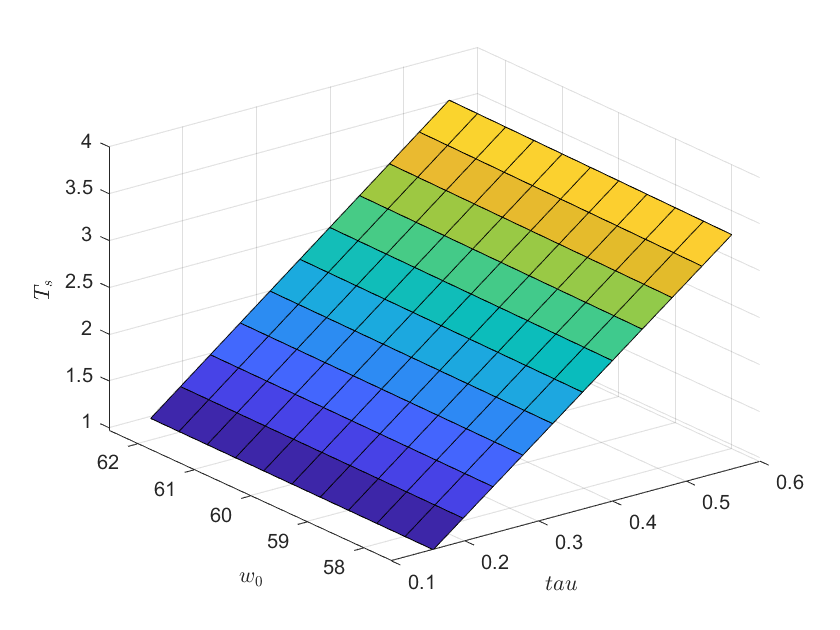

function [condition,isTerminal,direction] = at2percent(t,y,w_e)
condition = y<=0.002*w_e;
isTerminal = 1;
direction = 1;
end